clear all
close all;
% matlab code for dft 
x=input('inter the sequence you want the DFT');
N=length(x);
X=zeros(1,N);
for k=0:N-1
    for n=0:N-1
        X(k+1)=X(k+1)+x(n+1)*exp(-j*(2*pi*k*n)/N);
    end
end
disp(X);

   9.0000 + 0.0000i  -2.0000 + 3.0000i  -1.0000 - 0.0000i  -2.0000 - 3.0000i



subplot(3,2,1);
stem(x);
xlabel('n values-->>');
ylabel('amplitude-->>');
title('input values');
subplot(3,2,2);
stem(X);

xlabel('n values-->>');
ylabel('amplitude');
title('DFT of x');
abs(X);
magnitude=abs(X);
disp(magnitude);

    9.0000    3.6056    1.0000    3.6056



subplot(3,2,3);
stem(magnitude);
xlabel('n values');
ylabel('amplitude');
title('magnitude plot');
phase(X);
W=phase(X);
disp(W);

         0    2.1588    3.1416    4.1244



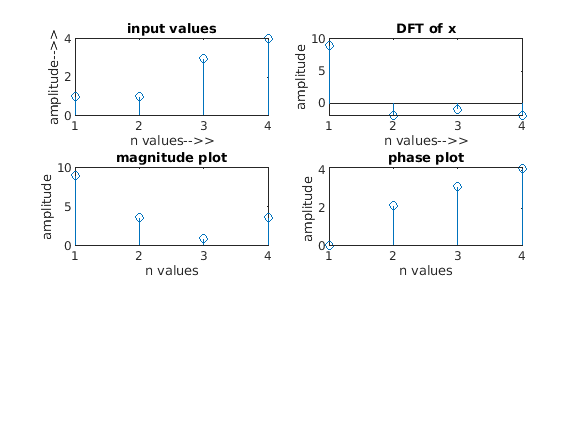

subplot(3,2,4);
stem(W);
xlabel('n values');
ylabel('amplitude ');
title('phase plot');